This try will include averaging over neighbouring points to get a coarser mesh.

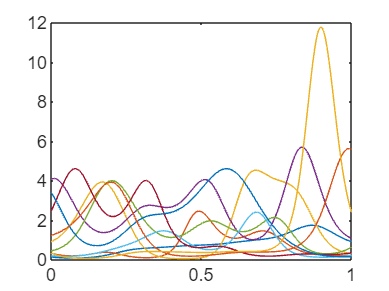

clc
clear


randomfield = 2;
I = 256;  % Finest mesh size
M = 10^2;
N = 10;
nu = 'infinity';
sigma = 0.5;
rel_err = zeros([I+1 1]);
x = linspace(0, 1, I+1);

C = Matern_specialcases_only(x, nu);
[EVec, EVal] = eig(C);
SV = zeros([I 1]);
EVec = flip(EVec, 2);
for k=1:I
    SV(k) = sqrt(EVal(I+1-k, I+1-k));
end

rng(1)
x_hat = linspace(0, 1, N + 1);
Y = normrnd(0, 1, [N M]);
a = zeros([M I+1]);
a_coarse = zeros([M I+1])

for sample=1:M
    if randomfield == 1 
        ind = zeros([length(x) N]);
        % Calculate for every node in the I mesh
        for l=1:length(x)
            % Check for every node in I mesh if its in [x^(k-1), x^(k)]
            for r=2:N+1
                if (x(l) >= x_hat(r-1) & x(l) <= x_hat(r))
                    ind(l, r-1) = Y(r-1, sample);
                else
                    ind(l, r-1) = 0;
                end
            end
        end
        stairs = crop(ind);
        a(sample, :) = 1 + 0.5*stairs;
    end

    if randomfield == 2
        inner = zeros([I+1 N]);
        for k=1:N
            inner(:, k) = SV(k)*Y(k, sample).*EVec(:, k);
        end

        kappa = sum(inner, 2);
        a(sample, :) = exp(kappa);
    end
end



for i=1:10
    plot(x, a(i, :))
    hold on;
end